# `Ch5_10_1`

频率采样设计法

采样点数为奇数


$$\begin{array}{l}
N=33\\
\omega_c =0\ldotp 5\pi 
\end{array}$$


要求滤波器具有线性相位特性

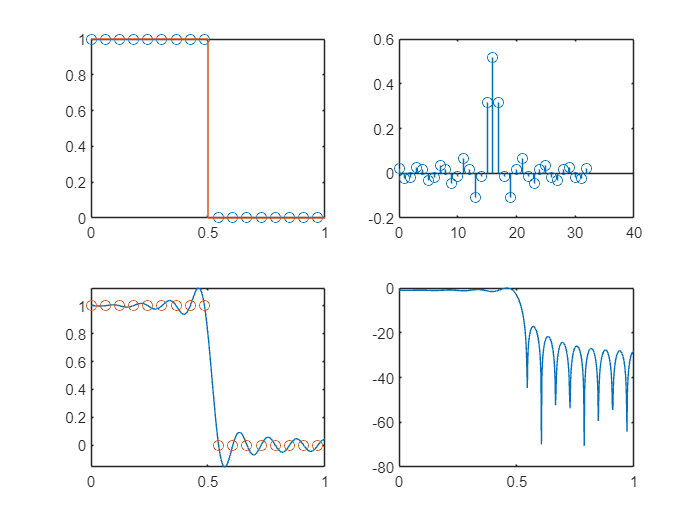

N = 33; 
Wc = 0.5;
alpha = (N-1)/2; 
l = 0:N-1;
wl = (2*pi/N)*l;
kt = floor(N*Wc/2);
Hrs = [ones(1,kt+1),zeros(1,N-2*kt-1),ones(1,kt)];
Hdr = [1,1,0,0]; 
wdl = [0,Wc,Wc,1];
k1 = 0:floor((N-1)/2); 
k2 = floor((N-1)/2)+1:N-1;
angH = [-alpha*(2*pi)/N*k1, alpha*(2*pi)/N*(N-k2)];
H = Hrs.*exp(1i*angH);
h = real(ifft(H,N));
[db,mag,pha,grd,w] = freqz_m(h,1);
[Hr,ww,a,L] = hr_type1(h);
subplot(2,2,1); plot(wl(1:alpha+1)/pi,Hrs(1:alpha+1),'o',wdl,Hdr); 
subplot(2,2,2); stem(l,h); 
subplot(2,2,3); plot(ww/pi,Hr,wl(1:alpha+1)/pi,Hrs(1:alpha+1),'o');
subplot(2,2,4); plot(w/pi,db); 